# Modeling LGN

Using LSY's email and CHSL 2022

Goal: Use the equations to generate LGN input patterns, then fix in precomputations.

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
DataFolder3 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3LGNSimuData/']; % V1D2

addpath(DataFolder3)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Figures/Demo081723/']; % V1D2

## 1. Calibration of LGN dynamics

I(t) = I_B = 0.1/ms, \tau_leak = 0.1/ms

N(t) = sum of Poisson timed kicks with rate 1/ms and size 0.075

When V reaches a threshold V_th, the cell fires, V is reset to 0 and the dynamics resumes.

Exact value of V_th (\approx 1) is chosen to give ~20 spikes/s.

Time step of simulation : 0.1 ms; Once V_th is found it will be fixed.

fGoal = 20; % Goal of BG LGN Frs: 20 Hz = 20 times/s

dt = 0.1; T = 1000 * 1e3;
I_B = 0.100; tau_L = 0.1; % ALL Units in MS!!
% \tau_leak = 0.1/ms = 1/10 ms, the time scale is faster than Leak of L4
% neurons
lambdaN = 0.1; fN = 0.075;

V_thre = 1.002; % this needs testing!
V_res = 0;

TGrid = 0:dt:T;
pPoiss = lambdaN * dt;
NSeq = double(rand(1,length(TGrid)) < pPoiss) .* ...
    (double(rand(1,length(TGrid)) <= 1/2)*2 - 1);

% at most this many spikes, unlikely for more
SpTime = zeros(2*fGoal * floor(T/1e3), 1);

Start simulation for BG LGN

V_LGN = zeros(size(TGrid)); % start from 0 then simulate
TInd = 1;
SpInd = 1;
tic
while TInd < length(TGrid)
    V_LGN(TInd+1) = V_LGN(TInd) + ...
        dt * (I_B - tau_L*(V_LGN(TInd) - V_res)) + ...
        NSeq(TInd) * fN;
    % Once firing: cross, reset, and record the timing
    if V_LGN(TInd+1) >= V_thre
        V_LGN(TInd+1) = V_res;
        SpTime(SpInd) = TGrid(TInd);
        SpInd = SpInd + 1;
    end
    TInd = TInd + 1;
end
toc

Elapsed time is 0.128083 seconds.



FLGN_bg = length(find(SpTime)) / floor(T/1e3);

## 2. visual inputs: drifting gratings

## LGN Kernels

close all

C = 1; % contrast
phi = 0; % initial phase
L0 = 1.0; % or 100? light internsity
Q0 = 0.5; % constant for visual gain; L0*Q0 can be combined.

spatial freq

g_abs = 2.5; % c/d, spatial frequency
theta = 0; % 0-pi
g = [cos(theta);sin(theta)];
g = g/norm(g) * g_abs;

now define receptive field

x_int = -1:0.005:1; y_int = -1:0.005:1;
[x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
sigma_a = 0.0894; sigma_b = 0.1259;
a = 1; b = 0.74; % parameters for the mexican hat
A = @(x,y,x0,y0) ... % x and y are are scalars or 2D meshgrids;
    ...% x0 and y0 are scalars:  the center of the kernel
    ( a/sigma_a^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_a^2) - ...
      b/sigma_b^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_b^2) )/pi;
Ax = A(x1,x2,0,0);

LGN temporal kernel

tau0 = 3.66; tau1 = 7.16; % all in ms
CompT = 36/31; % change the cross time from 36ms to 31ms
Koff = @(t) ... % t in ms
    (CompT*t).^6/tau0^7 .* exp( - (CompT*t)/tau0) - ...
    (CompT*t).^6/tau1^7 .* exp( - (CompT*t)/tau1);

2a: test different TFs

Jump for 3

fAll = 2:2:24; % Hz, cycles/second, temporal freqeuency;
FLGN_on_All = zeros(size(fAll));

fig1 = figure(1);
PlotId = [1:3:22, 2:3:23, 3:3:24];
for fId = 1:length(fAll) 
    f = fAll(fId)/1e3; %  normalized for ms

   Grating: spatiotemporal

    L = @(x,y,t) ... % x and y as above; t in second
        (C * sin(-2*pi*(g(1)*x + g(2)*y) + 2*pi*f*t + phi) + 1) * L0;
    Lxyt = L(x1,x2,0);

Plot figs to make sure everything is ok

%     TK = 0:0.1:100;
%     
%     figure
%     subplot(2,3,1)
%     plot(TK,Koff(TK));
%     xlabel('t (ms)'); ylabel('K^{off}')
%     title('K(t): LGN off temporal kernel')
%     
%     subplot(2,3,[2,3])
%     plot(x_int,Ax(floor(end/2),:))
%     %mesh(x1,x2,Ax)
%     %imagesc(-1:0.005:1,-1:0.005:1,Ax)
%     %set(gca,'YDir','Normal');
%     %colormap jet; colorbar
%     %axis([-0.5 0.5 -0.5 0.5])
%     xlabel('x (deg)'); ylabel('A(x)')
%     %axis square
%     xlim([-0.3 0.3]);%ylim([-0.3 0.3]);
%     title('A(x): LGN off spatial kernel')
%     grid on
% 
%     
%     tL = [0 25 50];
%     for ii = 1:length(tL)
%         subplot(2,length(tL),ii + 3)
%         imagesc(-1:0.005:1,-1:0.005:1,L(x1,x2,tL(ii)))
%         set(gca,'YDir','Normal'); colormap jet; colorbar
%         axis([-0.5 0.5 -0.5 0.5])
%         xlabel('x (deg)'); ylabel('y (deg)'); title(sprintf('%d ms',tL(ii)))
%         axis square
%     end

    %close all

### 2.1 Do integration for inputs

Q_Inter = @(x,y,s,t) Koff(s) * A(-x,-y,0,0) .* L(x,y,t-s);

Need to first precompute for all t, then quote from series;

    Tlength = 5; % 5s
    T_AL = 0:dt:1e3; %  time grid for 1s
    AL_allT = zeros(size(T_AL));

    x_int = -0.5:0.005:0.5; y_int = -0.5:0.005:0.5;

    [x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
    for ALId = 1:length(T_AL)
        AL_allT(ALId) = ...
            sum(A(-x1,-x2,0,0) .* L(x1,x2,T_AL(ALId)),'all') * ...
            (x_int(2)-x_int(1)) * (y_int(2)-y_int(1));
    end
    AL_allT = [repmat(AL_allT(1:end-1),1,Tlength),AL_allT(end)];

    Tlgn = 0:dt:5*1e3; % in ms
    TIdTrunc = floor(200/dt); % temporal window at most this large
    Koff_Int = Koff(Tlgn);
    Qt_All = zeros(size(Tlgn)); % Qt in every time bin
    for TId = 1:length(Tlgn)
        WinSize = min(TIdTrunc,TId);
        Qt_All(TId) = ...
            sum(Koff_Int(1:WinSize) .* AL_allT(TId:-1:TId-WinSize+1),'all') * dt;
    end

plot Qt

    % plot(Tlgn,Qt_All)
    % xlim([1e3 2e3])
    % xlabel('t (ms)'); title('Q(t)');

on and off I

    Qt_Use = Qt_All/1e3 * Q0; % modified by Q0;

    I_on  = I_B + Qt_Use; I_on(I_on<0) = 0;
    I_off = I_B - Qt_Use; I_off(I_off<0) = 0;

2.2 driven LGN cell:

    I_drive = I_on(floor(1e3/dt):end);

    f_drive_Goal = 100;
    T_drive = 4e3;
    TGrid = 0:dt:T_drive;
    pPoiss = lambdaN * dt;
    NSeq = double(rand(1,length(TGrid)) < pPoiss) .* ...
        (double(rand(1,length(TGrid)) <= 1/2)*2 - 1);

    % at most this many spikes, unlikely for more
    SpTime = zeros(2*f_drive_Goal * floor(T_drive/1e3), 1);

Start simulation for BG LGN

    V_LGN = zeros(size(TGrid)); % start from 0 then simulate
    TInd = 1;
    SpInd = 1;
    tic
    while TInd < length(TGrid)
        V_LGN(TInd+1) = V_LGN(TInd) + ...
            dt * (I_drive(TInd) - tau_L*(V_LGN(TInd) - V_res)) + ...
            NSeq(TInd) * fN;
        % Once firing: cross, reset, and record the timing
        if V_LGN(TInd+1) >= V_thre
            V_LGN(TInd+1) = V_res;
            SpTime(SpInd) = TGrid(TInd);
            SpInd = SpInd + 1;
        end
        TInd = TInd + 1;
    end
    toc

    FLGN_on_All(fId) = length(find(SpTime)) / floor(T_drive/1e3);

plot firing events and V

    subplot(8,3,PlotId(2*(fId-1)+1))
    plot(Tlgn,Qt_Use)
    xlim([1e3 2e3])
    title(sprintf('%dHz Q(t); LGN-V',fAll(fId)));
    
    subplot(8,3,PlotId(2*fId))
    hold on
    plot(TGrid,V_LGN);
    scatter(SpTime, ones(size(SpTime)),15,'r.')
    xlim([1e3 2e3])
    xlabel('t (ms)'); ylabel('V'); 
end

figure(2)
plot(fAll,FLGN_on_All,'o-')
xlabel('f (Hz)'); ylabel('LGN on cell firing rates')
grid on

## 3. LGN config and grating angles

C = 1; % contrast
for ONOFFDist = 0.17:0.02:0.19
for RowDist = 0.12%0.18:0.02:0.24
    fprintf('Row=%.2f,OnOFF=%.2f',RowDist,ONOFFDist)
for ThetaUse = 0:7.5:90
phi = 0; % initial phase
L0 = 1.0; % or 100? light internsity
Q0 = 0.5; % constant for visual gain; L0*Q0 can be combined.

spatial freq

g_abs = 2.5; % c/d, spatial frequency
theta = ThetaUse/180*pi; % 0-pi
g = [cos(theta);sin(theta)];
g = g/norm(g) * g_abs;

now define receptive field

x_int = -1:0.005:1; y_int = -1:0.005:1;
[x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
sigma_a = 0.0894; sigma_b = 0.1259;
a = 1; b = 0.74; % parameters for the mexican hat
A = @(x,y,x0,y0) ... % x and y are are scalars or 2D meshgrids;
    ...% x0 and y0 are scalars:  the center of the kernel
    ( a/sigma_a^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_a^2) - ...
      b/sigma_b^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_b^2) )/pi;

LGN temporal kernel

tau0 = 3.66; tau1 = 7.16; % all in ms
CompT = 36/31; % change the cross time from 36ms to 31ms
Koff = @(t) ... % t in ms
    (CompT*t).^6/tau0^7 .* exp( - (CompT*t)/tau0) - ...
    (CompT*t).^6/tau1^7 .* exp( - (CompT*t)/tau1);

Grating: spatiotemporal

f = 10/1e3;
L = @(x,y,t) ... % x and y as above; t in second
    (C * sin(-2*pi*(g(1)*x + g(2)*y) + 2*pi*f*t + phi) + 1) * L0;

LGN config

4 cells and 6 cells

% X0Y0All = ...
%     [0    0;
%      0    0.2;
%      0.15 0;
%      0.15 0.2];
% ONOFF = [true; true; false; false]; % true for on
X0Y0All = ...
    [0    0;
     0    RowDist;
     0    RowDist*2;
     ONOFFDist 0;
     ONOFFDist RowDist;
     ONOFFDist RowDist*2];
ONOFF = [true; true; true; false; false; false]; % true for on

Fig start

figure(3)
subplot(length(ONOFF)+1,2,2*length(ONOFF)+1)
hold on
imagesc(-0.5:0.005:0.5,-0.5:0.005:0.5,L(x1,x2,25),'AlphaData',0.5)
set(gca,'YDir','Normal'); colormap jet; colorbar
scatter(X0Y0All(ONOFF,1),X0Y0All(ONOFF,2),50,'w+','LineWidth',3)
scatter(X0Y0All(~ONOFF,1),X0Y0All(~ONOFF,2),50,'k+','LineWidth',3)
axis([-0.05 0.25 -0.05 0.40])
xlabel('x (deg)'); ylabel('y (deg)'); 
axis square
f_drive_Goal = 100;
Tlength = 10; % 5s
T_drive = (Tlength-1)*1e3;

SpTimeAll = zeros(2*f_drive_Goal * floor(T_drive/1e3), length(ONOFF));
for cellId = 1:length(ONOFF)
    tic
    
    T_AL = 0:dt:1e3; %  time grid for 1s
    AL_allT = zeros(size(T_AL));

    x_int = -0.5:0.005:0.5; y_int = -0.5:0.005:0.5;
    x0use = X0Y0All(cellId,1); y0use = X0Y0All(cellId,2);

    [x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
    for ALId = 1:length(T_AL)
        AL_allT(ALId) = ...
            sum(A(-x1,-x2,x0use,y0use) .* L(x1,x2,T_AL(ALId)),'all') * ...
            (x_int(2)-x_int(1)) * (y_int(2)-y_int(1));
    end
    AL_allT = [repmat(AL_allT(1:end-1),1,Tlength),AL_allT(end)];

    Tlgn = 0:dt:Tlength*1e3; % in ms
    TIdTrunc = floor(200/dt); % temporal window at most this large
    Koff_Int = Koff(Tlgn);
    Qt_All = zeros(size(Tlgn)); % Qt in every time bin
    for TId = 1:length(Tlgn)
        WinSize = min(TIdTrunc,TId);
        Qt_All(TId) = ...
            sum(Koff_Int(1:WinSize) .* AL_allT(TId:-1:TId-WinSize+1),'all') * dt;
    end

on and off I

    Qt_Use = Qt_All/1e3 * Q0; % modified by Q0;
    if ONOFF(cellId)
        I_dr = I_B + Qt_Use; I_dr(I_dr<0) = 0; % for on cell
    else
        I_dr = I_B - Qt_Use; I_dr(I_dr<0) = 0; % for off cell
    end

2.2 driven LGN cell:

Row=0.12,OnOFF=0.17

Elapsed time is 3.967677 seconds.
Elapsed time is 4.191354 seconds.
Elapsed time is 3.827384 seconds.
Elapsed time is 3.714043 seconds.
Elapsed time is 3.709367 seconds.
Elapsed time is 3.658935 seconds.
Elapsed time is 3.797791 seconds.
Elapsed time is 3.690670 seconds.
Elapsed time is 3.665205 seconds.
Elapsed time is 3.676048 seconds.
Elapsed time is 3.667186 seconds.
Elapsed time is 3.671156 seconds.
Elapsed time is 3.738181 seconds.
Elapsed time is 3.704414 seconds.
Elapsed time is 3.690717 seconds.
Elapsed time is 3.673724 seconds.
Elapsed time is 3.667267 seconds.
Elapsed time is 3.850312 seconds.
Elapsed time is 3.909598 seconds.
Elapsed time is 3.780056 seconds.
Elapsed time is 3.738602 seconds.
Elapsed time is 3.728526 seconds.
Elapsed time is 3.716397 seconds.
Elapsed time is 3.706265 seconds.
Elapsed time is 3.869534 seconds.
Elapsed time is 4.123903 seconds.
Elapsed time is 3.759044 seconds.
Elapsed time is 3.751662 seconds.
Elapsed time is 3.689041 seconds.
Elapsed time i

Row=0.12,OnOFF=0.19

Elapsed time is 3.801487 seconds.
Elapsed time is 3.742596 seconds.
Elapsed time is 3.765923 seconds.
Elapsed time is 3.715597 seconds.
Elapsed time is 3.772173 seconds.
Elapsed time is 3.821032 seconds.
Elapsed time is 3.816084 seconds.
Elapsed time is 3.945920 seconds.
Elapsed time is 3.967970 seconds.
Elapsed time is 3.990202 seconds.
Elapsed time is 3.806880 seconds.
Elapsed time is 3.669943 seconds.
Elapsed time is 3.842849 seconds.
Elapsed time is 3.723098 seconds.
Elapsed time is 3.846691 seconds.
Elapsed time is 3.744098 seconds.
Elapsed time is 3.697283 seconds.
Elapsed time is 3.737884 seconds.
Elapsed time is 3.929336 seconds.
Elapsed time is 3.724886 seconds.
Elapsed time is 3.787206 seconds.
Elapsed time is 3.780492 seconds.
Elapsed time is 3.848388 seconds.
Elapsed time is 3.745370 seconds.
Elapsed time is 3.872183 seconds.
Elapsed time is 3.776612 seconds.
Elapsed time is 4.118232 seconds.
Elapsed time is 4.036186 seconds.
Elapsed time is 3.932835 seconds.
Elapsed time i

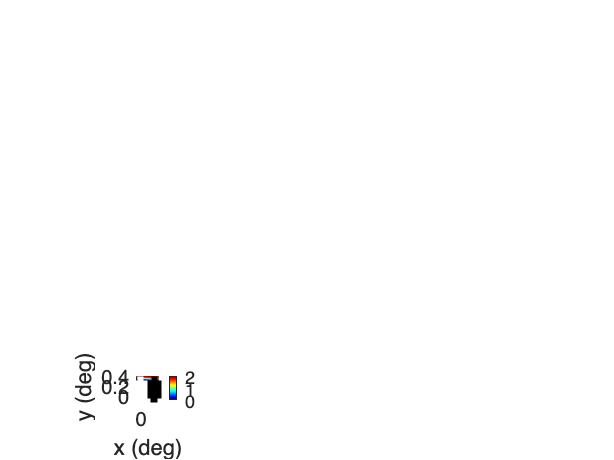

Elapsed time is 3.854291 seconds.
Elapsed time is 3.773534 seconds.
Elapsed time is 3.780630 seconds.
Elapsed time is 3.759116 seconds.
Elapsed time is 3.801708 seconds.
Elapsed time is 3.757005 seconds.


    I_drive = I_dr(floor(1e3/dt):end);

    
    TGrid = 0:dt:T_drive;
    pPoiss = lambdaN * dt;
    NSeq = double(rand(1,length(TGrid)) < pPoiss) .* ...
        (double(rand(1,length(TGrid)) <= 1/2)*2 - 1);

    % at most this many spikes, unlikely for more
    SpTime = zeros(2*f_drive_Goal * floor(T_drive/1e3), 1);

    V_LGN = zeros(size(TGrid)); % start from 0 then simulate
    TInd = 1;
    SpInd = 1;
    
    while TInd < length(TGrid)
        V_LGN(TInd+1) = V_LGN(TInd) + ...
            dt * (I_drive(TInd) - tau_L*(V_LGN(TInd) - V_res)) + ...
            NSeq(TInd) * fN;
        % Once firing: cross, reset, and record the timing
        if V_LGN(TInd+1) >= V_thre
            V_LGN(TInd+1) = V_res;
            SpTime(SpInd) = TGrid(TInd);
            SpInd = SpInd + 1;
        end
        TInd = TInd + 1;
    end
    SpTimeAll(1:length(SpTime),cellId) = SpTime;
    toc

%     subplot(length(ONOFF)+1,2,2*cellId-1)
%     plot(Tlgn,Qt_Use)
%     xlim([1e3 2e3])
%     title(sprintf('cell #%d',cellId));
%     
%     subplot(length(ONOFF)+1,2,2*cellId)
%     hold on
%     plot(TGrid,V_LGN);
%     scatter(SpTime, ones(size(SpTime)),15,'r.')
%     xlim([1e3 2e3])
%     xlabel('t (ms)'); ylabel('V'); 
end

SpTimeMix = reshape(SpTimeAll,size(SpTimeAll,1)*size(SpTimeAll,2),1);
SpTimeMix(SpTimeMix == 0) = [];
WinL = 30; % 15ms sliding windows
WinStep = 2; % 2ms step size
WinCenter = (0:WinStep:T_drive)'; 
SlideWin = zeros(length(WinCenter),2);
SlideWin(:,1) = WinCenter - WinL/2; SlideWin(:,2) = WinCenter + WinL/2; 
TotalRateWin = zeros(size(SlideWin,1),1);
for WinId = 1:size(SlideWin,1)
    TotalRateWin(WinId) = ...
        length(...
        find(SpTimeMix>=SlideWin(WinId,1) & SpTimeMix<=SlideWin(WinId,2) )...
        ) / (WinL/1e3);
end

SaveStr = 'LGNSimu';
SaveStrUse = sprintf('%s_Cell%d_Row%.2f_Col%.2f_deg%.1f_SF%.1f_TF%d_TSimu%d',...
    SaveStr,length(ONOFF),RowDist, ONOFFDist,theta/pi*180,g_abs,floor(f*1e3),Tlength);

save([SaveToFolder sprintf('%s.mat',SaveStrUse)],...
    'WinCenter','SlideWin','TotalRateWin',...
    'X0Y0All','ONOFF',... %locations of LGN cells
    'Koff','tau0','tau1','CompT',... %temp kernel
    'A','a','b','sigma_a','sigma_b') %spatial kernel
end
end
end

% subplot(length(ONOFF)+1,2,2*length(ONOFF)+2)
% hold on
% plot(WinCenter,TotalRateWin);
% scatter(SpTimeMix, 100*ones(size(SpTimeMix)),15,'r.')
% xlim([1e3 2e3])
% xlabel('t (ms)');
% ylabel('rates (Hz)')
% title('Total LGN frs')

## 4. Extract LGN input patterns

Tlength = 100;
figure(10)
CellNum = 4; % 4 or 6
for ThetaUse = 0:15:90
    theta = ThetaUse/180*pi; % 0-pi
    SaveStr = 'LGNSimu';
    SaveStrUse = sprintf('%s_Cell%d_deg%.1f_SF%.1f_TF%d_TSimu%d',...
        SaveStr,CellNum,theta/pi*180,g_abs,floor(f*1e3),Tlength);

    load([SaveToFolder sprintf('%s.mat',SaveStrUse)])

    subplot(2,1,1)
    hold on
    plot(WinCenter,TotalRateWin,...
        'DisplayName',sprintf('%.1f deg',ThetaUse));
    xlim([1e3 1.4e3])
    xlabel('t (ms)');
    ylabel('rates (Hz)')
    title('Total LGN frs')
    

Compute the averaged LGN input rate per cycle

    WinStep = SlideWin(2,1) - SlideWin(1,1);
    OneSecGrids = 0:WinStep:1e3-WinStep;
    OneCycSteps = floor(length(OneSecGrids)/floor(f*1e3));
    LGNRateUse = TotalRateWin(OneCycSteps+1:end-1-OneCycSteps);
    LGNRateAve = mean(...
        reshape(LGNRateUse/CellNum,OneCycSteps,floor(length(LGNRateUse)/OneCycSteps)),...
        2); % average each cycle
    LGNRateStd = std(...
        reshape(LGNRateUse/CellNum,OneCycSteps,floor(length(LGNRateUse)/OneCycSteps)),0,...
        2); 

    subplot(2,1,2)
    hold on
    h = errorbar(0:WinStep:(OneCycSteps-1)*WinStep,LGNRateAve',LGNRateStd',...
        'DisplayName',sprintf('%.1f deg',ThetaUse),'LineWidth',0.8,...
        'CapSize',0);
    set(h.Children, 'LineWidth', 0.5); % setting the error bars thinner
    xlabel('t (ms)');
    ylabel('rates (Hz/cell)')
    title('LGN frs averaged')
    grid on
    legend
end

4a every single angle

Tlength = 10;
figure(11)
g_abs = 2.5; 
f = 10/1e3;

for RowDist = 0.12
    
for ONOFFDist = [0.17,.19]
    subpId = 1;


for ThetaUse = 0:7.5:90
    for CellNum = 6 % 4 or 6
        theta = ThetaUse/180*pi; % 0-pi
        SaveStr = 'LGNSimu';
        SaveStrUse = sprintf('%s_Cell%d_Row%.2f_Col%.2f_deg%.1f_SF%.1f_TF%d_TSimu%d',...
            SaveStr,CellNum,RowDist, ONOFFDist,theta/pi*180,g_abs,floor(f*1e3),Tlength);

        load([SaveToFolder sprintf('%s.mat',SaveStrUse)])


Compute the averaged LGN input rate per cycle

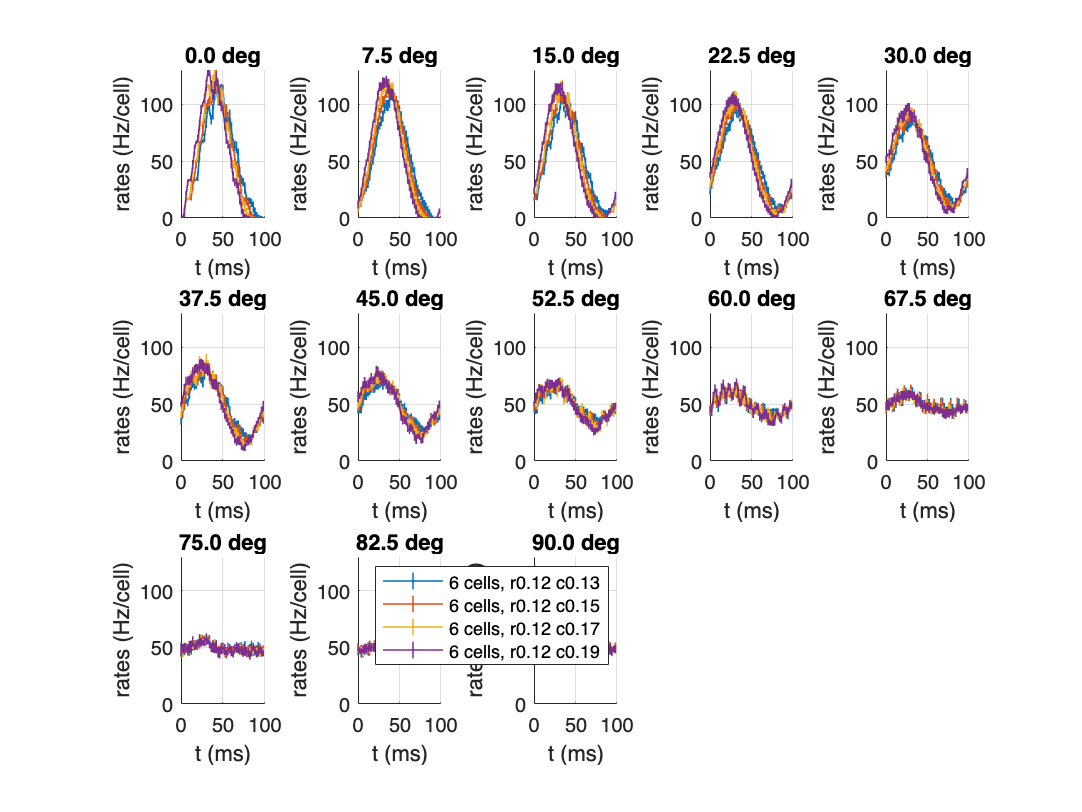

        WinStep = SlideWin(2,1) - SlideWin(1,1);
        OneSecGrids = 0:WinStep:1e3-WinStep;
        OneCycSteps = floor(length(OneSecGrids)/floor(f*1e3));
        LGNRateUse = TotalRateWin(OneCycSteps+1:end-1-OneCycSteps);
        LGNRateAve = mean(...
            reshape(LGNRateUse/CellNum,OneCycSteps,floor(length(LGNRateUse)/OneCycSteps)),...
            2); % average each cycle
        LGNRateStd = std(...
            reshape(LGNRateUse/CellNum,OneCycSteps,floor(length(LGNRateUse)/OneCycSteps)),0,...
            2);

        subplot(3,5,subpId)
        hold on
        h = errorbar(0:WinStep:(OneCycSteps-1)*WinStep,LGNRateAve',LGNRateStd',...
            'DisplayName',sprintf('%d cells, r%.2f c%.2f',CellNum,RowDist,ONOFFDist),...
            'LineWidth',0.8,...
            'CapSize',0);
        set(h.Children, 'LineWidth', 0.5); % setting the error bars thinner
        xlabel('t (ms)');
        ylabel('rates (Hz/cell)')
        title(sprintf('%.1f deg',ThetaUse))
        grid on
        ylim([0 130])

        if CellNum == 6
            subpId = subpId + 1;
        end
    end
    if subpId == 14
        legend
    end
end
end
end


%close all